#### 2.3.1) A

fs = 250 ;%since the axis should be in MHz
Ts = 1/fs;
f_0 = 250*51/256

f_0 = 49.8047

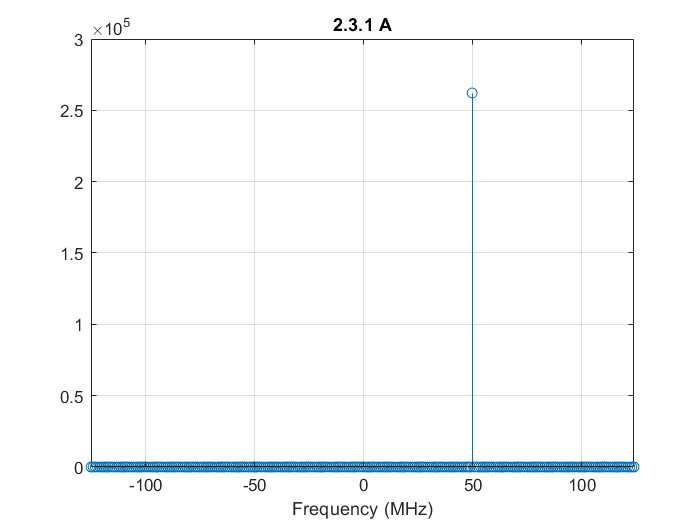

nfft = 256;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft));
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
xlabel("Frequency (MHz)")
title("2.3.1 A")
grid on

nfft*Ts/(1/f_0)

ans = 51

#### 2.3.1) B

f_0 = 250 * 51.5/256

f_0 = 50.2930

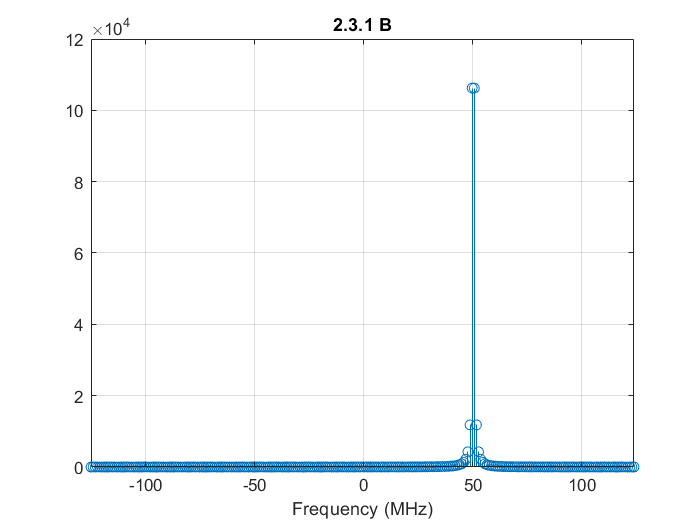

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft));
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
xlabel("Frequency (MHz)")
title("2.3.1 B")
grid on

nfft*Ts/(1/f_0)

ans = 51.5000

#### 2.3.1) C

f_0 = 250*51/256

f_0 = 49.8047

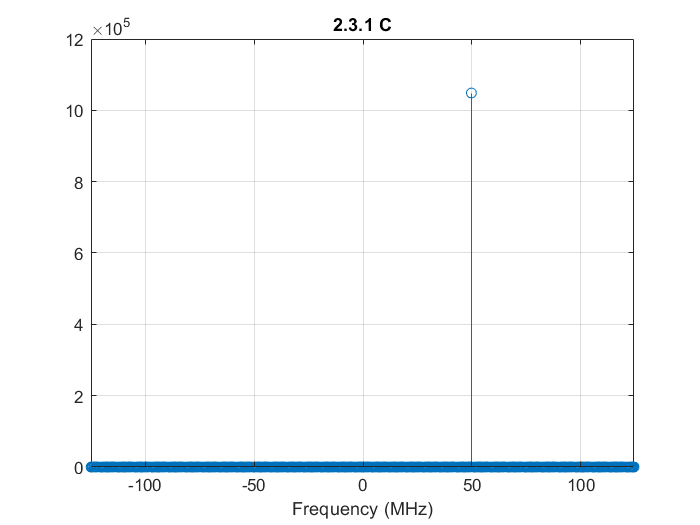

nfft = 512;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft));
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 C")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0)

ans = 102

#### 2.3.1) D

f_0 = -250*51/256

f_0 = -49.8047

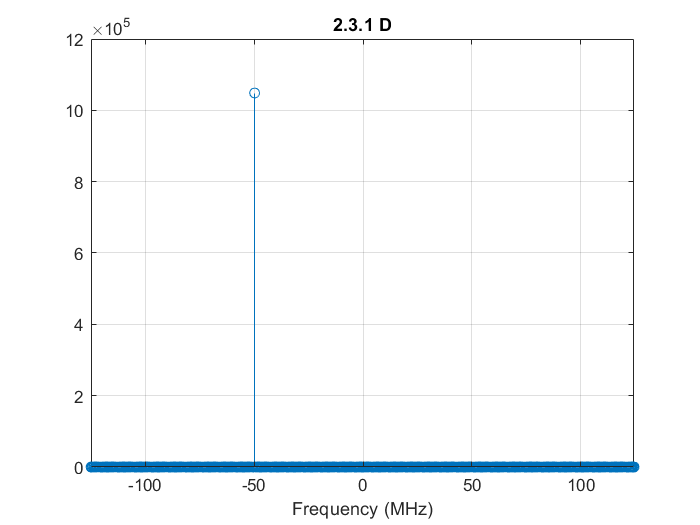

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft));
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 D")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0)

ans = -102

#### 2.3.1) E

A = 4;
f_0 = 250*(153)/256

f_0 = 149.4141

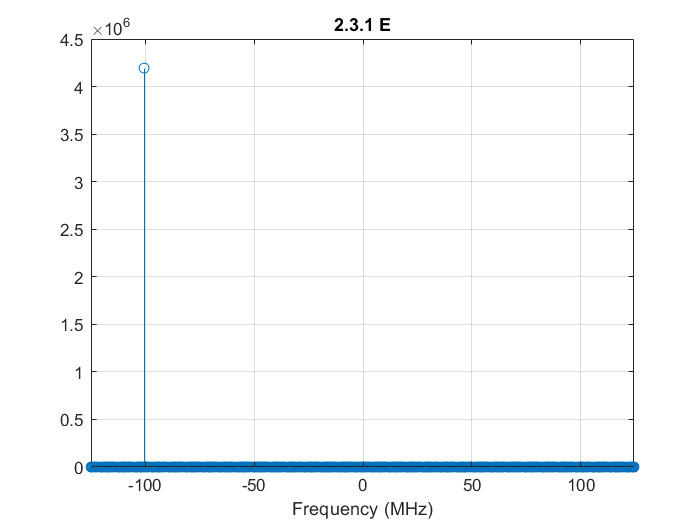

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft));
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 E")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0)

ans = 306

#### 2.3.1) F

FFT samples from our spectrum of signal, since the samples distance from each other is fs/nfft. if f_0 is an integral multiple of fs/nfft then will observe a peak in frequency domain of signal.

it means that: f_0/(fs/nff) be ineteger. in the case that the result is not an integer, we can see a leakage in our spectrum, for instance in part A we can see that:

Ts = 1/250;
f_0 = 250*51/256;
nfft = 256;
result = nfft*Ts/(1/f_0)

result = 51

and for part B:

f_0 = 250*51.5/256;
result = nfft*Ts/(1/f_0)

result = 51.5000

As we can see in part A result is 51 and in part B is 51.5. since there is a frequency leakage in part B.

We could also compute part C, D, and E as follows

result C = 102

result D = -102

result E = 306

Also in Part E since our sampling frequency is 250MHz, we can show frequencies in range of [-125, 125] MHz. Since the spectrum of signal has value higher than fs/2 and from nyquist theorm we know that a periodic signal must be sampled at more than twice of highest frequency compoenen of signal. Therefore, in our example we have aliasing and retained signal frequency peak is not where we expected.

#### 2.3.1) G

The coefficient should be added is nfft, it means that result should be divided by nfft:

Xf = fftshift(fft(x, nfft))/nfft;

**As we can see new figures are:**

fs = 250 ;%since the axis should be in MHz
Ts = 1/fs;
f_0 = 250*51/256

f_0 = 49.8047

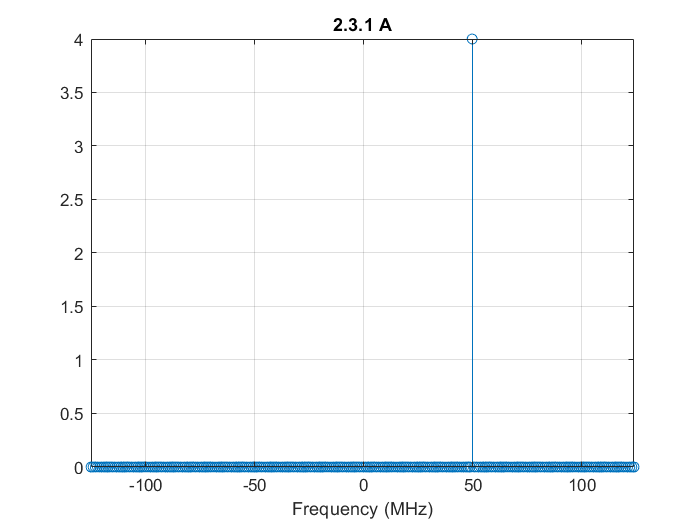

nfft = 256;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
xlabel("Frequency (MHz)")
title("2.3.1 A")
grid on

f_0 = 250 * 51.5/256

f_0 = 50.2930

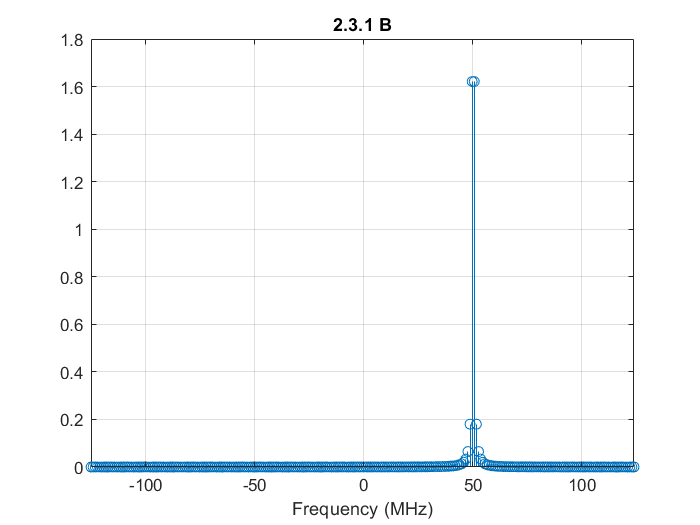

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
xlabel("Frequency (MHz)")
title("2.3.1 B")
grid on

nfft*Ts/(1/f_0);
f_0 = 250*51/256

f_0 = 49.8047

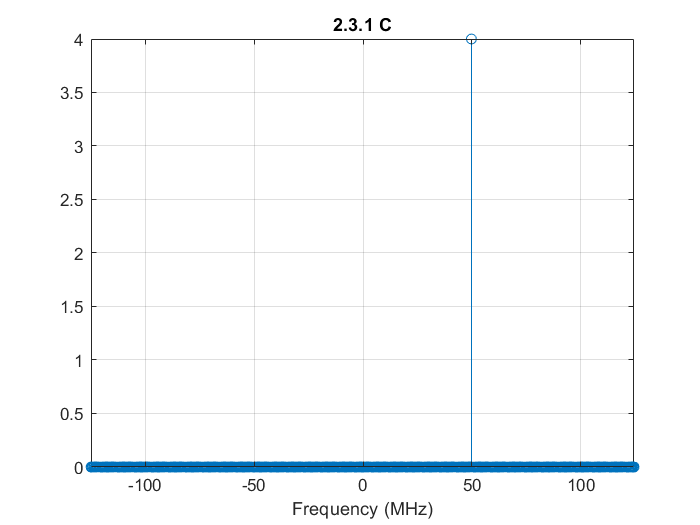

nfft = 512;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 C")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0);
f_0 = -250*51/256

f_0 = -49.8047

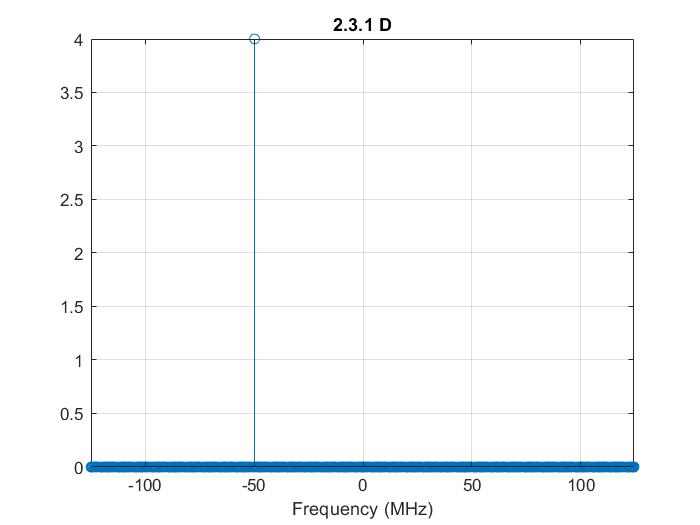

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 D")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0)

ans = -102

A = 4;
f_0 = 250*(153)/256

f_0 = 149.4141

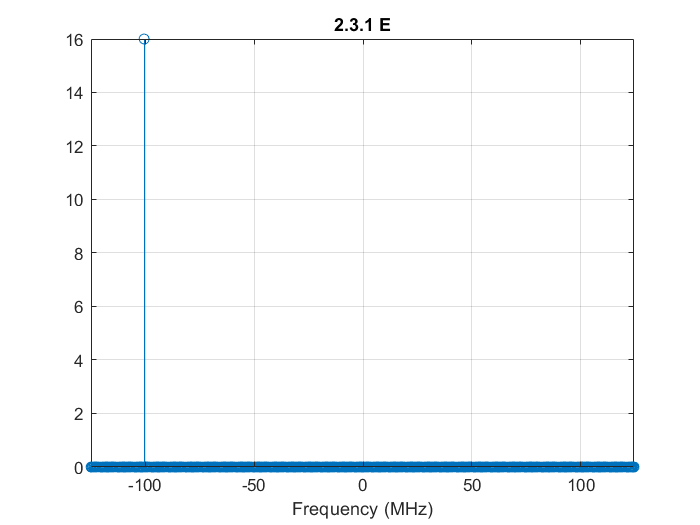

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
stem(f, abs(Xf).^2)
xlim([f(1),f(end)])
title("2.3.1 E")
xlabel("Frequency (MHz)")
grid on

nfft*Ts/(1/f_0)

ans = 306

#### 2.3.1) H

As mentioned earlied we are sampling from spectrum with length of fs/nfft. if nfft increases the resolution also increases. for part A we can shift our spectrum by resolution as follows:

f_0_new = f_0 + fs/nfft

fs = 250 ;%since the axis should be in MHz
Ts = 1/fs;
f_0 = 250*51/256

f_0 = 49.8047

f_0_new = f_0 + fs/nfft

f_0_new = 50.7813

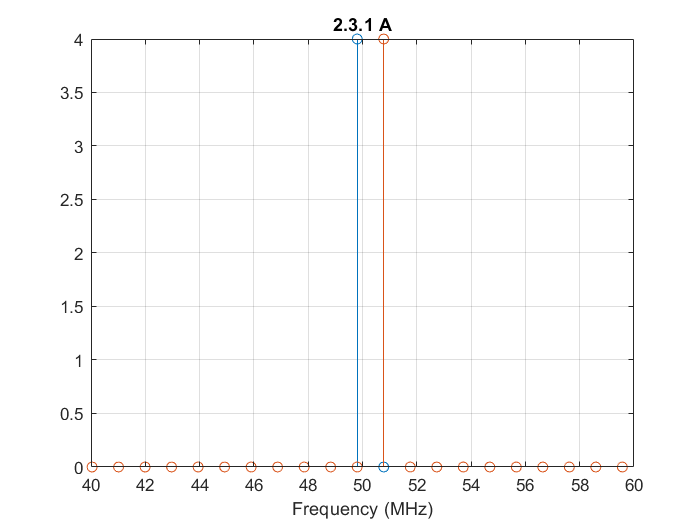

nfft = 256;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
x_new = A * exp(1i * 2*pi*f_0_new* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
Xf_new = fftshift(fft(x_new, nfft))/nfft;
stem(f, abs(Xf).^2)
hold on
stem(f, abs(Xf_new).^2)
hold off
xlim([40,60])
xlabel("Frequency (MHz)")
title("2.3.1 A")
grid on

#### 2.3.1)G

As Partheval Theorm approves, Power in Time domain is equal to Power in frequency domain.

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Power_in_Time = x*transpose(conj(x))/length(x)

Power_in_Time = 4

Xf = fftshift(fft(x, nfft))/nfft;
Power_in_Frequency = Xf*transpose(conj(Xf))

Power_in_Frequency = 4

#### 2.3.1)H

Part A

fs = 250 ;
Ts = 1/fs;
f_0 = 250*51/256

f_0 = 49.8047

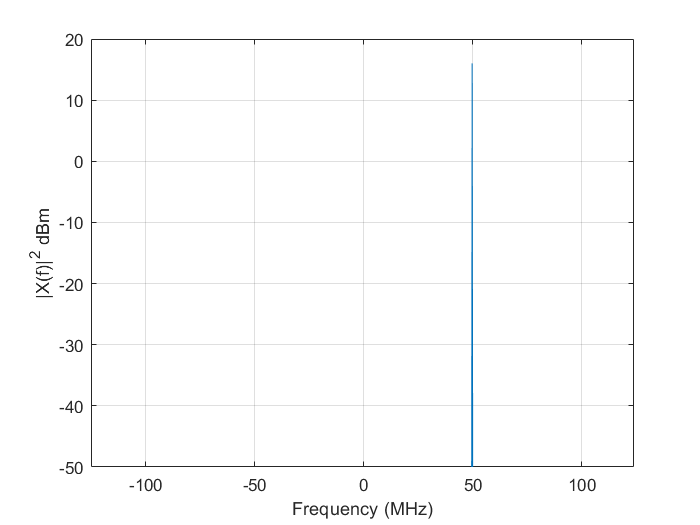

nfft = 256;
f = [0:nfft-1]/nfft*fs - fs/2 ;
n = (0:nfft-1);
A = 2;
x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
R = 50;
power = 10 * log10((abs(Xf).^2)/(2*R)) + 30;
plot(f, power)
xlim([f(1),f(end)]);
ylim([-50 20]);
xlabel("Frequency (MHz)")
ylabel("|X(f)|^2 dBm")
grid on

Part B

f_0 = 250 * 51.5/256

f_0 = 50.2930

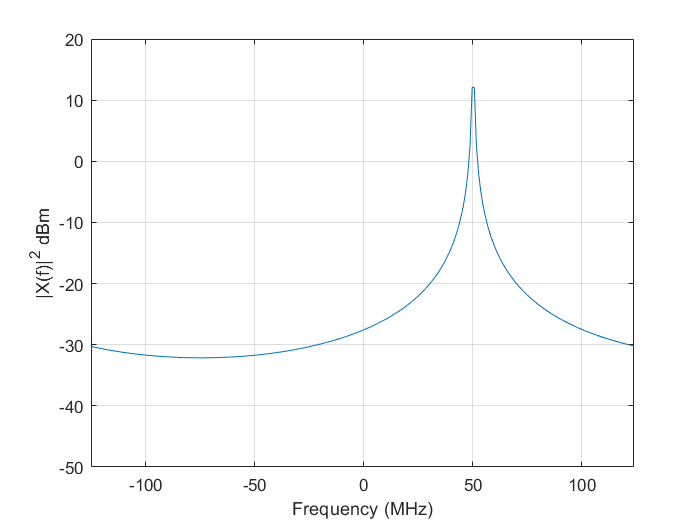

x = A * exp(1i * 2*pi*f_0* n*Ts) ;
Xf = fftshift(fft(x, nfft))/nfft;
R = 50;
power = 10 * log10((abs(Xf).^2)/(2*R)) + 30;
plot(f, power)
xlim([f(1),f(end)]);
ylim([-50 20]);
xlabel("Frequency (MHz)")
ylabel("|X(f)|^2 dBm")
grid on